**Step 1: Physically Install PiCam on Raspi**

Physical camera installation [https://thepihut.com/blogs/raspberry-pi-tutorials/16021420-how-to-install-use-the-raspberry-pi-camera](https://thepihut.com/blogs/raspberry-pi-tutorials/16021420-how-to-install-use-the-raspberry-pi-camera)

Note: if you get strange numbers in the middle of your camera, rebooting the pi generally works to get rid of it

**Step 2: Connect to Raspi (assumes Raspi setup has already been completed)**

% Clear old vars
clear
% Connect to raspi
rpi = raspi()

rpi =   raspi with properties:

         DeviceAddress: '192.168.1.213'               
                  Port: 18734                         
             BoardName: 'Raspberry Pi 3 Model B+'     
         AvailableLEDs: {'led0'}                      
  AvailableDigitalPins: [4,5,6,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27]
  AvailableSPIChannels: {'CE0','CE1'}                 
     AvailableI2CBuses: {'i2c-1'}                     
      AvailableWebcams: {'bcm2835-isp (platform:bcm2835-isp)','mmal service 16.1 (platform:bcm2835-v4l2)'}
           I2CBusSpeed: 100000                        

  Supported peripherals


**Step 3: Connect to PiCam**

Documentation on pi cam usage in MatLab: https://www.mathworks.com/help/supportpkg/raspberrypiio/ref/cameraboard.html

% Note: use webcam function instead if using a USB camera
cam = cameraboard(rpi,'Resolution','1280x720')

cam =   cameraboard with properties:

                    Name: Camera Board   
              Resolution: '1280x720'      (View available resolutions)
                 Quality: 10              (1 to 100)
                Rotation: 0               (0, 90, 180 or 270)
          HorizontalFlip: 0              
            VerticalFlip: 0              
               FrameRate: 30              (2 to 90)
               Recording: 0              

   Picture settings
              Brightness: 50              (0 to 100)
                Contrast: 0               (-100 to 100)
              Saturation: 0               (-100 to 100)
               Sharpness: 0               (-100 to 100)

   Exposure and AWB
            ExposureMode: 'auto'          (

**Step 4: Take a photo with the PiCam**

% Take a photo using the camera
img = snapshot(cam)

img = 720×1280×3 uint8 array
img(:,:,1) =

   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   

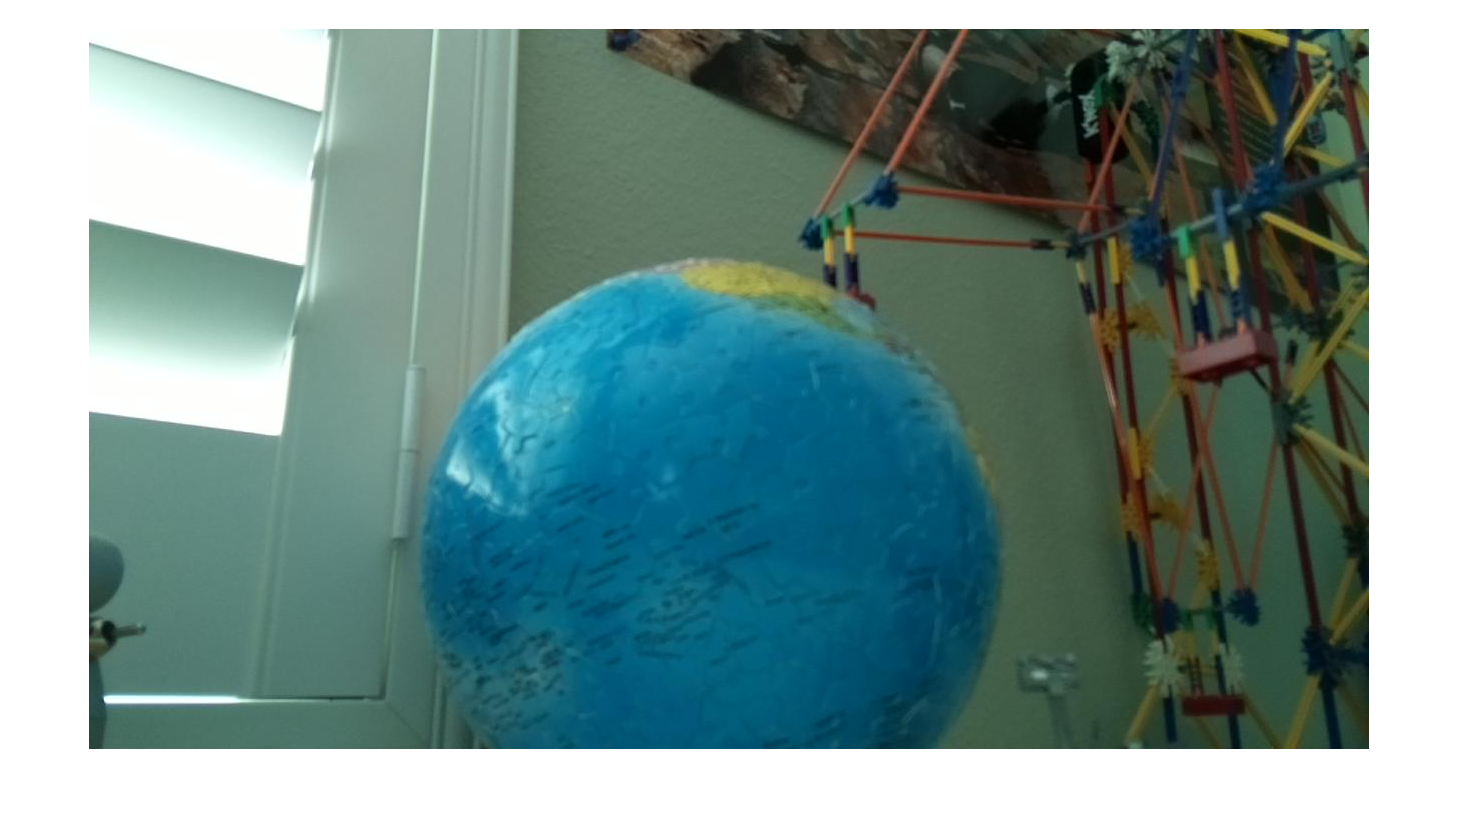


% Display image
figure, imshow(img)

**Step 5: Use Matlab's colorThresholder to select target color**

In the GUI, select a color space of your choice (HSV generally works pretty well)

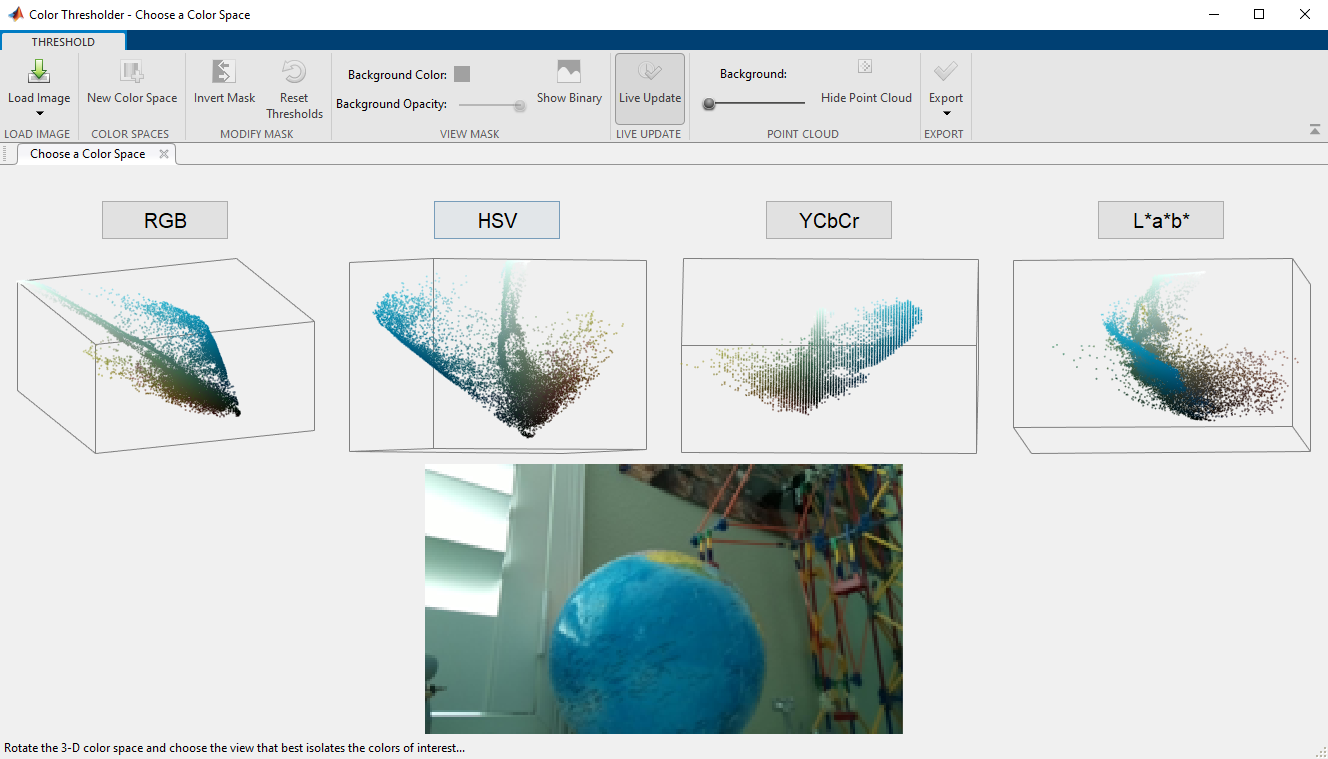

Then adjust the sliders until only the target color remains visible (it's ok if it's not perfect - just make sure the largest remaining blob is in the color you want)

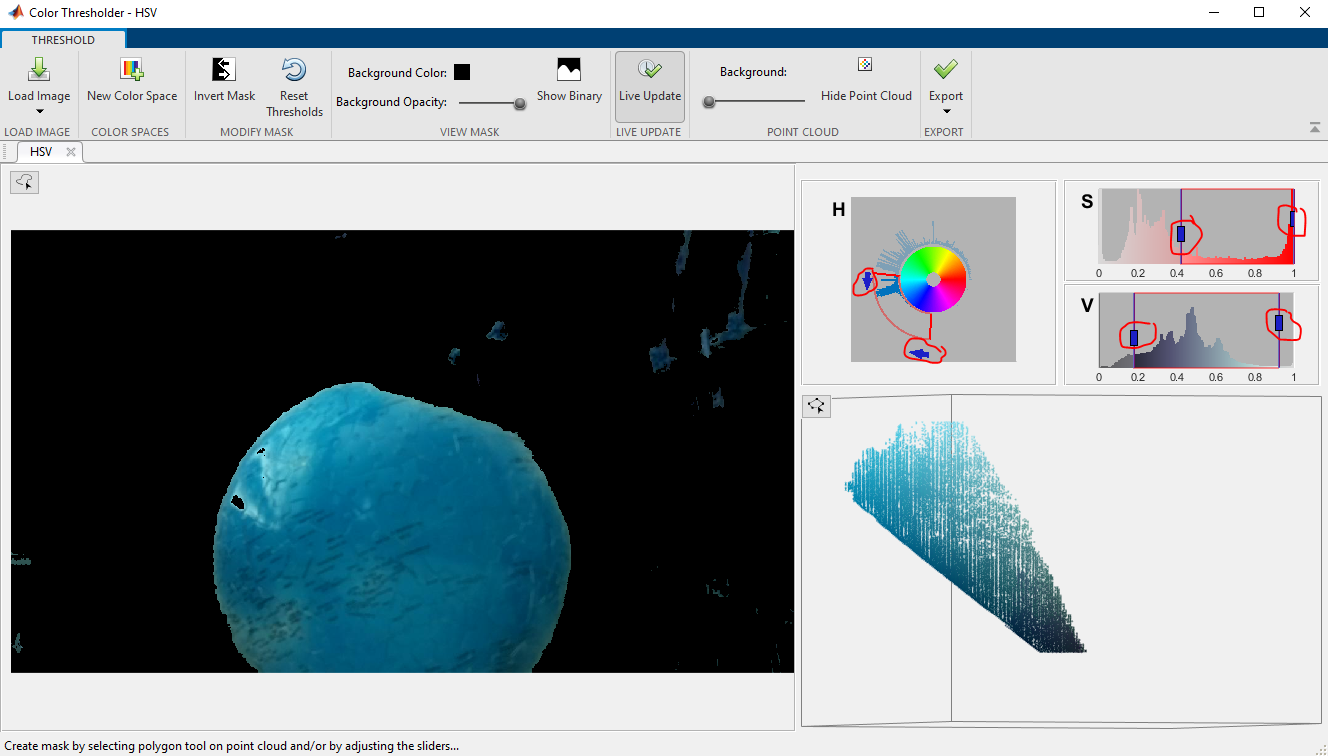

When you're done, click Export>Export Function

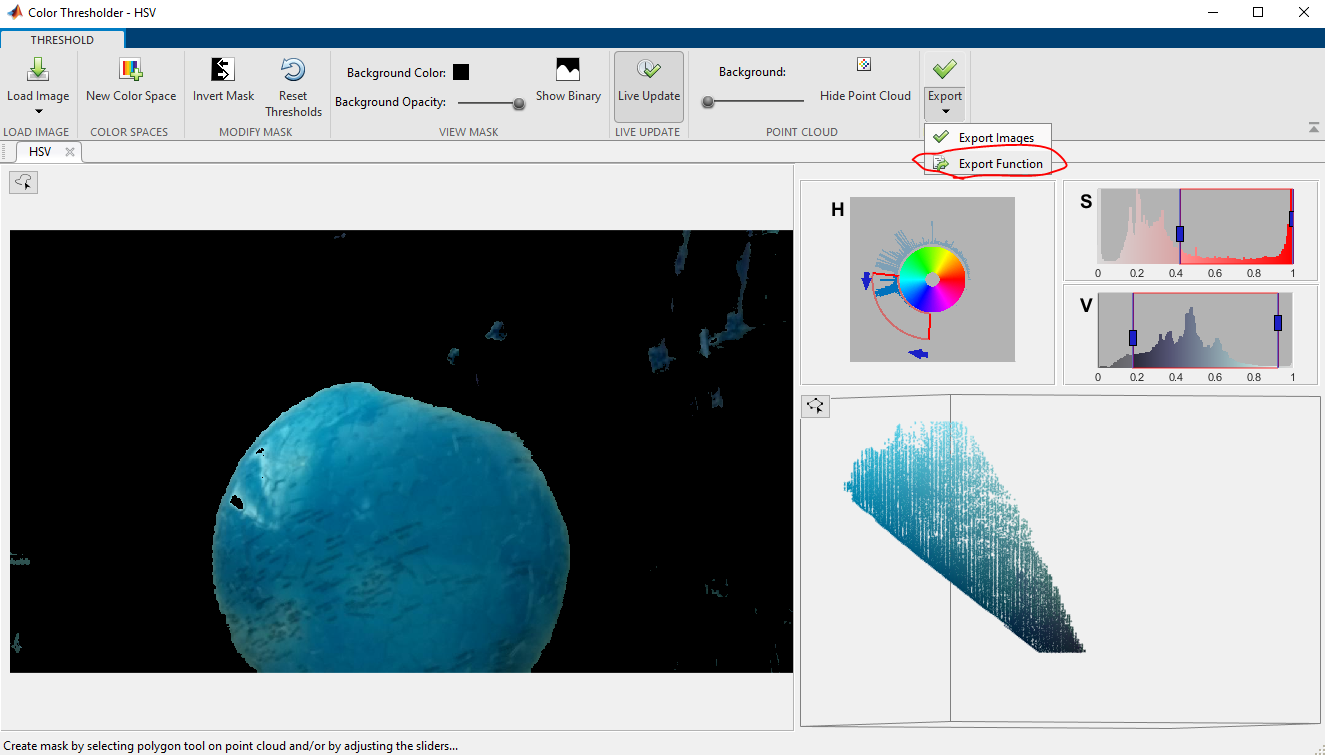

A new window will pop up - copy/paste the output function at the bottom of this notebook (be sure to replace the existing `createMask` function

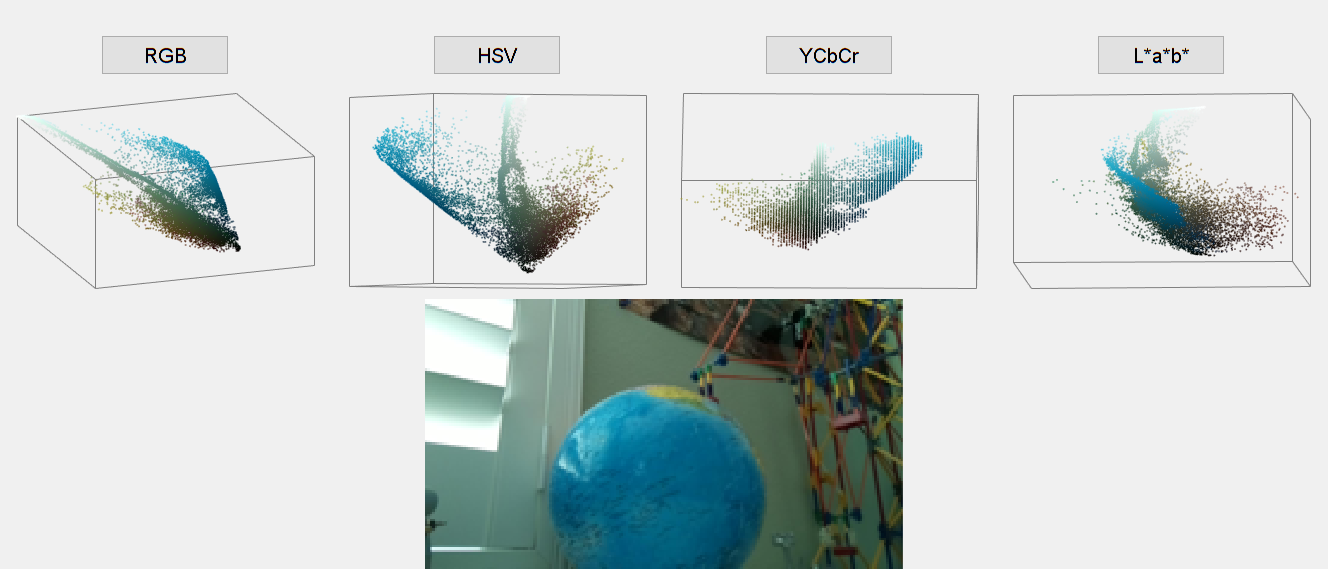

colorThresholder(img)

**Step 6: Use our new createMask function to find a whale (or any other object of a particualar color)!**

Note: Keep in mind that the camera coordinates look like this, where the origin is in the upper-left hand corner

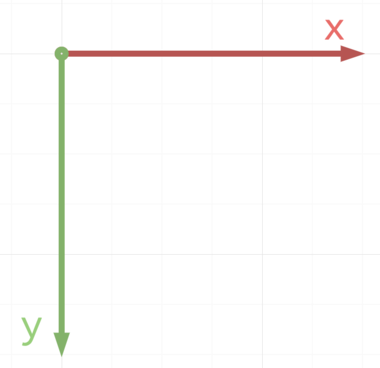

(image source: [https://www.google.com/url?sa=i&url=https%3A%2F%2Fkidscancode.org%2Fgodot_recipes%2Fmath%2Ftransforms%2F&psig=AOvVaw3elRTHRp0qUMXfe3yDbpcR&ust=1612200508628000&source=images&cd=vfe&ved=0CA0QjhxqFwoTCIiPk4nZxu4CFQAAAAAdAAAAABAD](https://www.google.com/url?sa=i&url=https%3A%2F%2Fkidscancode.org%2Fgodot_recipes%2Fmath%2Ftransforms%2F&psig=AOvVaw3elRTHRp0qUMXfe3yDbpcR&ust=1612200508628000&source=images&cd=vfe&ved=0CA0QjhxqFwoTCIiPk4nZxu4CFQAAAAAdAAAAABAD))

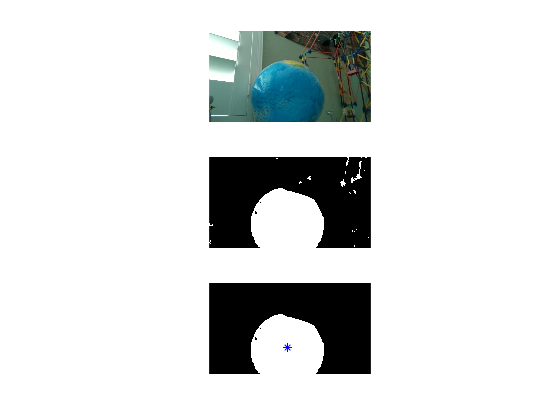

X-pixel value: 617.3022 
Y-pixel value: 508.0246 


% Choose whether to display frames for debugging
displayFrames = true;
[whaleX, whaleY] = findWhale(img, displayFrames);

**Misc. Notes**

Available exposure modes for PiCam: 'auto', 'night', 'nightpreview', 'backlight', 'spotlight', 'sports', 'snow', 'beach', 'verylong', 'fixedfps', 'antishake', 'fireworks'

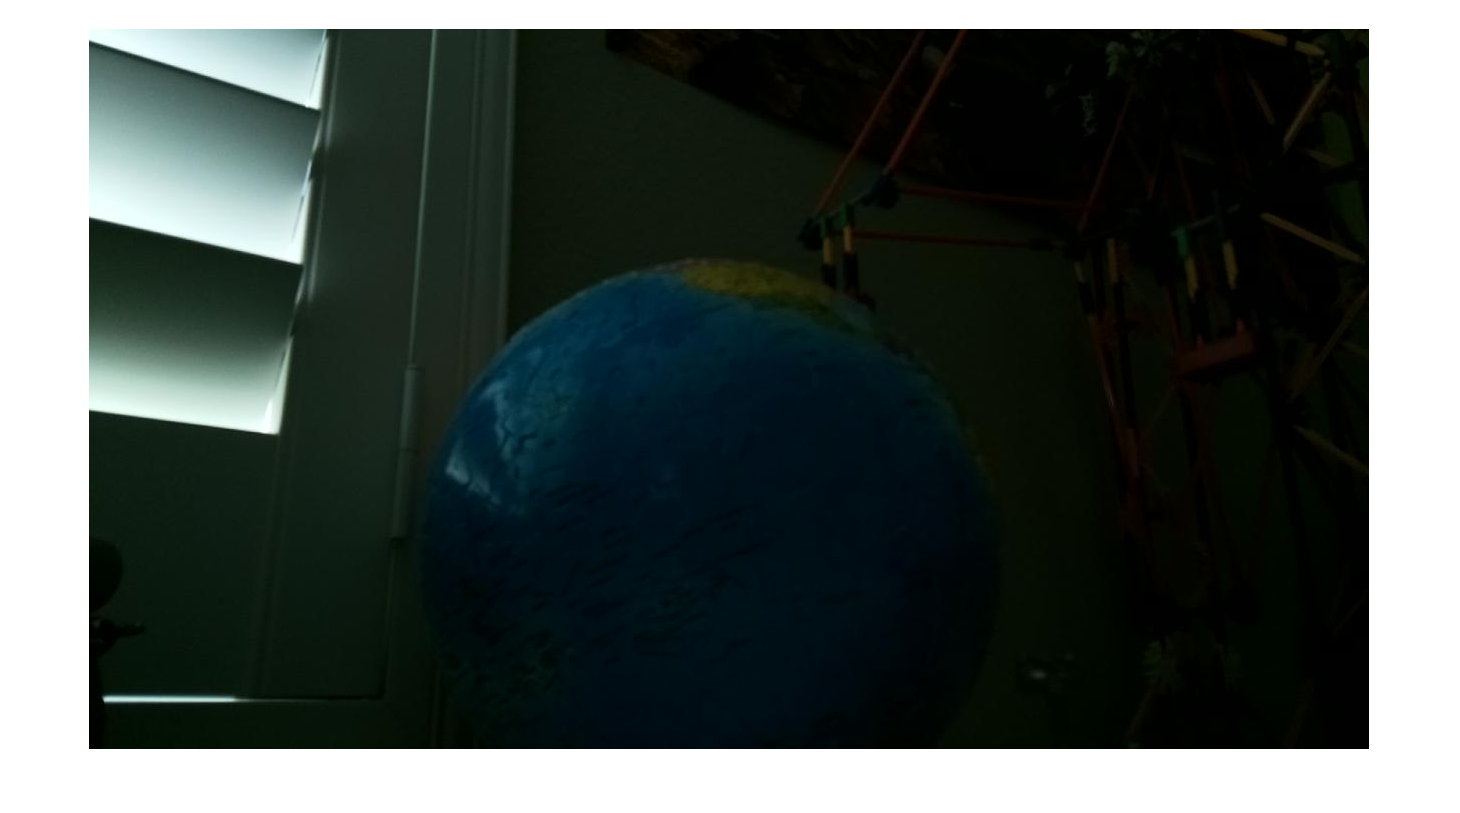

cam.ExposureMode='spotlight';
img = snapshot(cam);
figure, imshow(img)

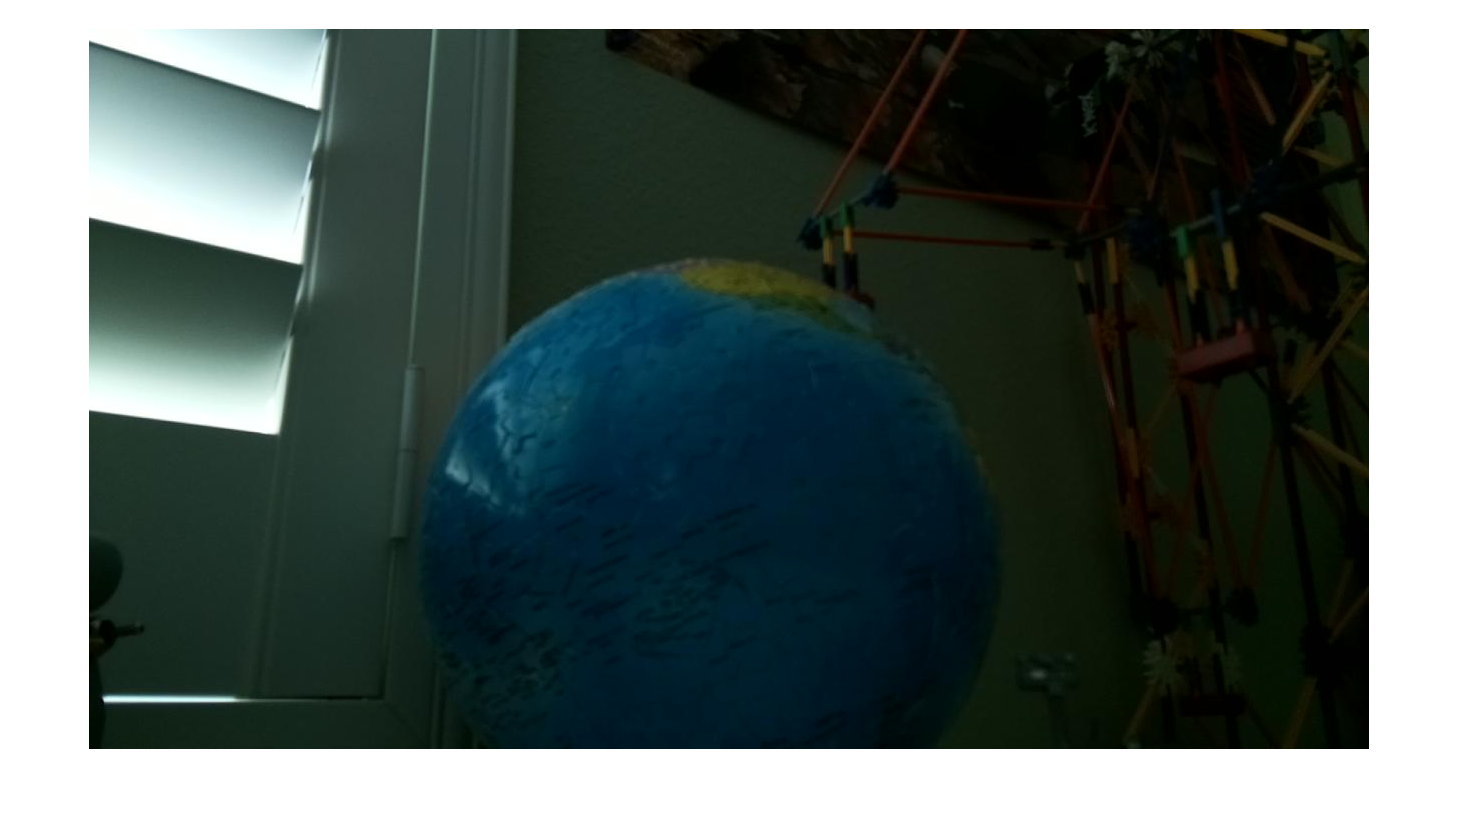


cam.ExposureMode='night';
img = snapshot(cam);
figure, imshow(img)

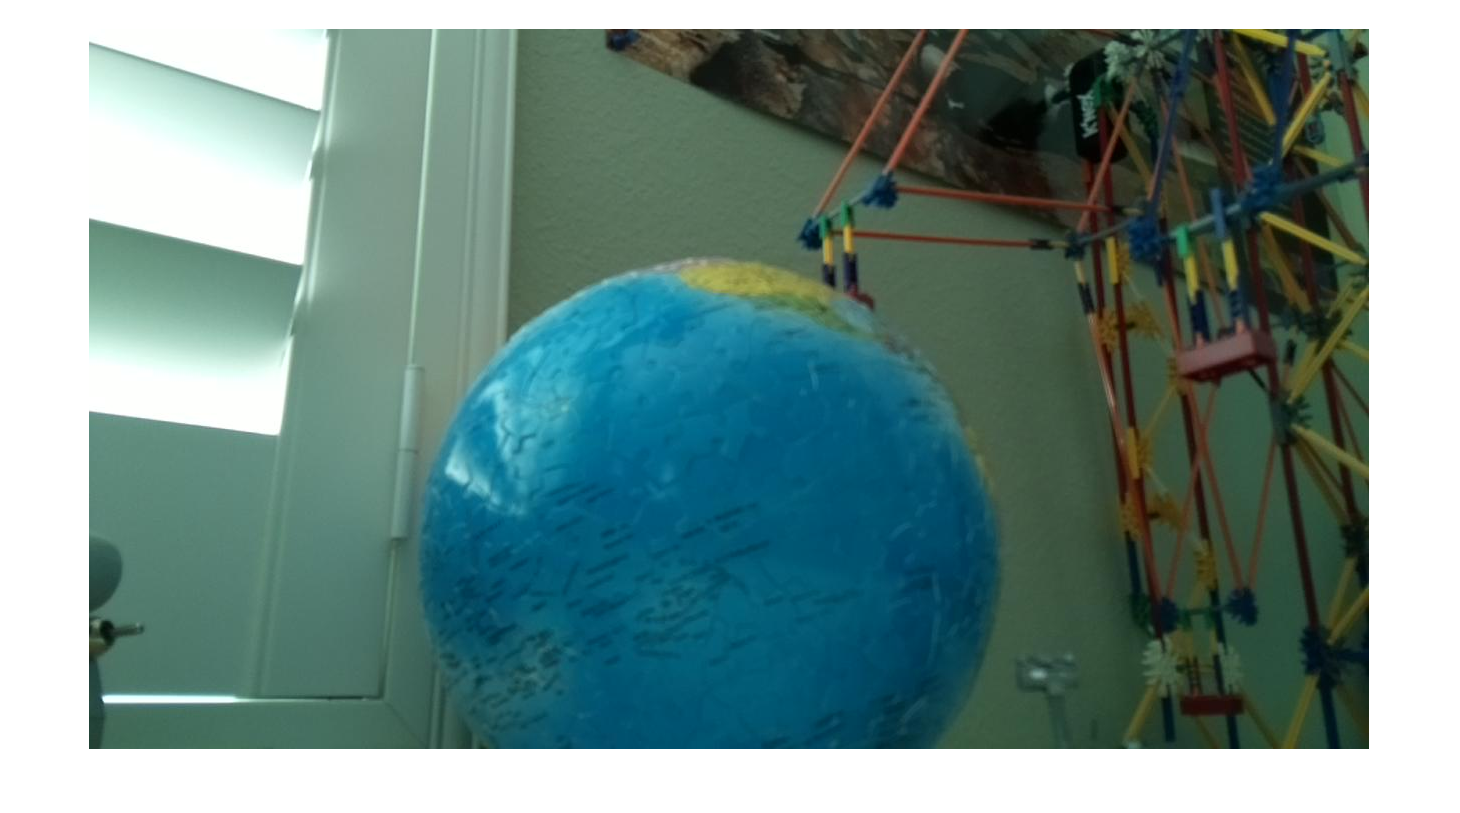


cam.ExposureMode='auto';
% Note: There apprears to be a slight delay between setting the mode and it
% actually working - might be worth considering adding a delay here
img = snapshot(cam);
figure, imshow(img)

**Don't forget to shutdown to avoid corrupting data when you're done!**

system(rpi, 'sudo shutdown -h now')

Connection to SSH server at 192.168.1.213 closed. Clear the hardware communication object and re-create it to establish connection.

**Functions**

% https://www.mathworks.com/help/images/ref/colorthresholder-app.html
% https://www.mathworks.com/matlabcentral/answers/374906-how-to-segment-blue-color-object-on-this-images

function [BW,maskedRGBImage] = createMask(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 31-Jan-2021
%------------------------------------------------------


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.483;
channel1Max = 0.740;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.421;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.179;
channel3Max = 0.923;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end


function [targetX, targetY] = findWhale(frame, displayBool)
    % Use our auto-generated function to extract regions of the image that 
    % are the color we want
    [BW, maskedRGBImage] = createMask(frame);

    % Create labels for all regions
    [L, num] = bwlabel(BW, 8);
    
    % Compute size of each continuous region, find largest region
    count_pixels_per_obj = sum(bsxfun(@eq,L(:),1:num));
    
    % Create new mask that only contains largest region
    [~,ind] = max(count_pixels_per_obj);
    biggest_blob = (L==ind);
    
    % Compute center of this region
    s = regionprops(biggest_blob,'centroid');
    centroids = cat(1,s.Centroid);
    
    % Assign center of largest region to our output variables
    targetX = centroids(1);
    targetY = centroids(2);
    
    % Display the results   
    if displayBool   
        figure,
        % Display original image
        subplot(311),imshow(frame)
        % Display color-masked image
        subplot(312),imshow(BW)
        % Display the largest blob with the center marked
        subplot(313),imshow(biggest_blob)
        hold on
        plot(centroids(:,1),centroids(:,2),'b*')
        hold off
        
        fprintf(['X-pixel value: %.4f \n'], targetX)
        fprintf(['Y-pixel value: %.4f \n'], targetY)
    end
end
